% Week 12 example code for training a simple SVM classifier on the
% CUB_200_2011_Subset20classes dataset using SIFT features.
%
% Author: Roland Goecke
% Date created: 26/04/2022
% Date last updated: 10/04/2023

close all;
clear variables;
clc;

## Read the training, validation and test partitions from the relevant

folder = "..\week9\CUB_200_2011_Subset20classes\";
trainingImageNames = readtable(fullfile(folder, "train.txt"), ...
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate.txt", ...
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test.txt", ...
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Create lists of image names for training, validation and test subsets.

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Training set class distribution:');

Training set class distribution:


countEachLabel(trainingImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Validation set class distribution:');

Validation set class distribution:


countEachLabel(validationImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Test set class distribution:');

Test set class distribution:


countEachLabel(testImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## The images all have different spatial resolutions (width x height), so

targetSize = [224, 224];
trainingImageDS_Resized = transform(trainingImageDS, @(x) imresize(x,targetSize));
validationImageDS_Resized = transform(validationImageDS, @(x) imresize(x,targetSize));
testImageDS_Resized = transform(testImageDS, @(x) imresize(x,targetSize));

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
cdsTraining = combine(trainingImageDS_Resized, labelsTraining);
labelsValidation = arrayDatastore(validationImageDS.Labels);
cdsValidation = combine(validationImageDS_Resized, labelsValidation);
labelsTest = arrayDatastore(testImageDS.Labels);
cdsTest = combine(testImageDS_Resized, labelsTest);

## Display a sample image from the datastore

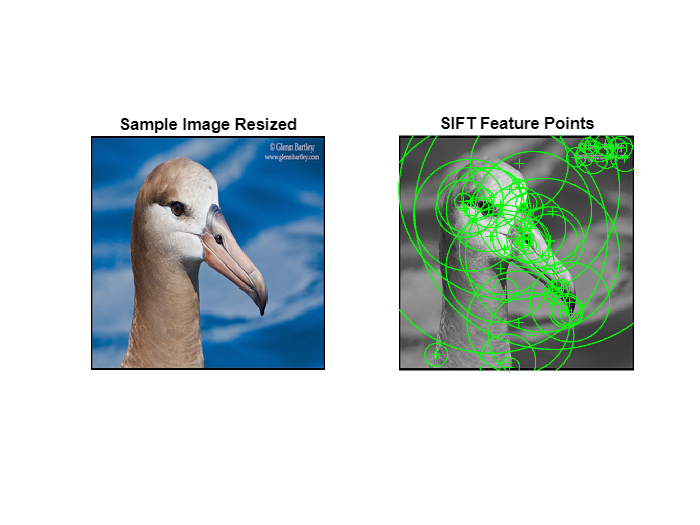

figure(1);
img = cdsTraining.read{1};
SIFTpoints = detectSIFTFeatures(rgb2gray(img));
subplot(1, 2, 1);
imshow(img);
title('Sample Image Resized');
subplot(1, 2, 2);
imshow(rgb2gray(img)); hold on;
title('SIFT Feature Points');
plot(SIFTpoints.selectStrongest(50));
hold off;

## Extract SIFT features

% Define some limits to the number of features to be used
numFeatures = 50;
maxFeatures = 100;

% Start by extracting features from the training set via the helper function.
% These features will be used to train the classifier.
[trainingFeatures, trainingLabels] = ...
    helperExtractSIFTFeaturesFromImageSet(trainingImageDS_Resized.UnderlyingDatastores{1, 1}, numFeatures, maxFeatures);

% Extract features from the test set as well.
[testFeatures, testLabels] = ...
    helperExtractSIFTFeaturesFromImageSet(testImageDS_Resized.UnderlyingDatastores{1, 1},  numFeatures, maxFeatures);

## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

Found GPU:


    Index                     Name                      ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _______________________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3050 Ti Laptop GPU"          "8.6"               true              false     



## Train a multi-class SVM

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
Copying objective function to workers...
Done copying objective function to workers.
|================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |
|================================================================================================|
|    1 |       3 | Accept |     0.92492 |      31.896 |      0.9039 |     0.91592 |       1.7985 |
|    2 |       3 | Accept |     0.91291 |      32.065 |      0.9039 |     0.91592 |   2.8381e-08 |
|    3 |       3 | Best   |      0.9039 |      32.037 |      0.9039 |     0.91592 |       13.231 |
|    4 |       3 | Accept |     0.92042 |      31.932 |      0.9039 |     0.91592 |    5.491e-06 |
|    5 |     

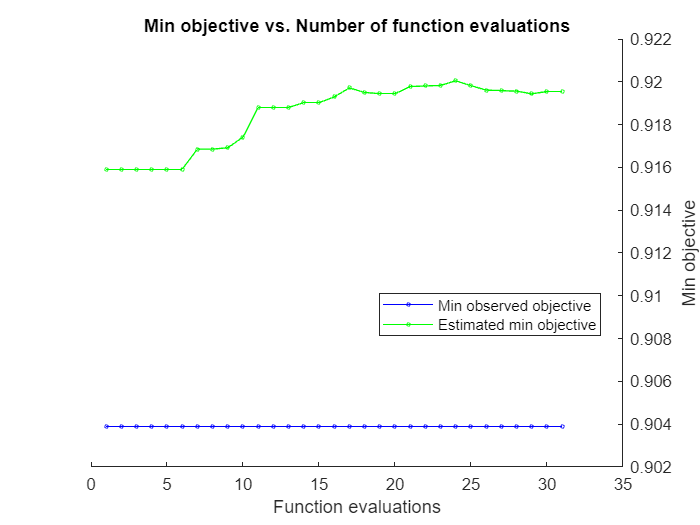

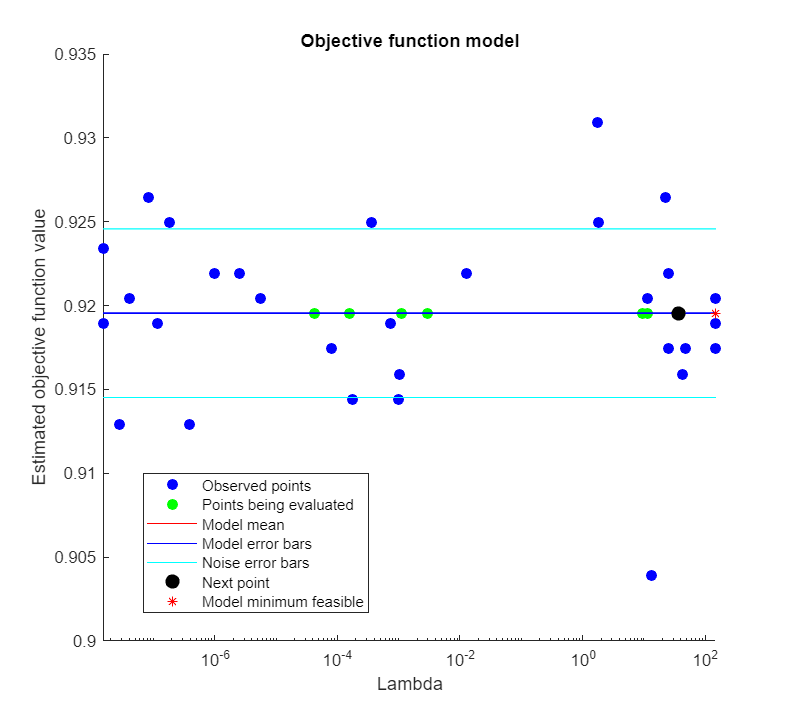


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 31
Total elapsed time: 133.4773 seconds
Total objective function evaluation time: 918.5301

Best observed feasible point:
    Lambda
    ______

    13.231

Observed objective function value = 0.9039
Estimated objective function value = 0.91955
Function evaluation time = 32.0367

Best estimated feasible point (according to models):
    Lambda
    ______

    150.06

Estimated objective function value = 0.91955
Estimated function evaluation time = 29.47



t = templateLinear('Solver', 'dual');
options = struct('UseParallel', true);

% fitcecoc uses multiple SVM learners and a 'One-vs-One' encoding scheme.
SVMClassifier = fitcecoc(trainingFeatures, trainingImageDS.Labels, 'Learners', t, ...
    'OptimizeHyperparameters', {'Lambda'}, ...
    'HyperparameterOptimizationOptions', options);%

## Test the accuracy on the test partition

YPred = predict(SVMClassifier, testFeatures);
YTest = testImageDS.Labels;

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest) % Output on command line

accuracy = 0.0946

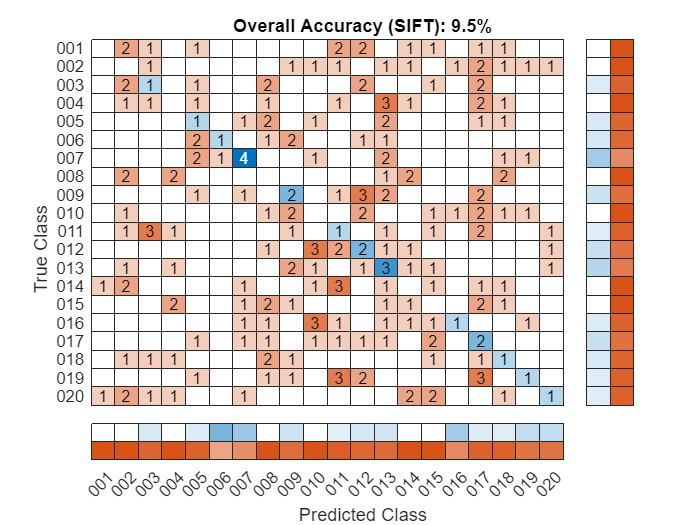


% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy (SIFT): "+ string(round(accuracy*100, 1)) +"%");